# Laplace Transform

#### a)

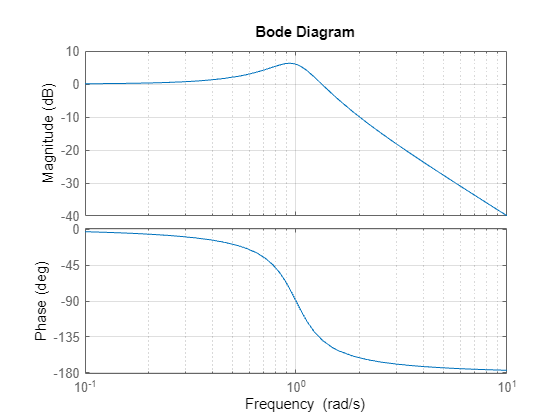

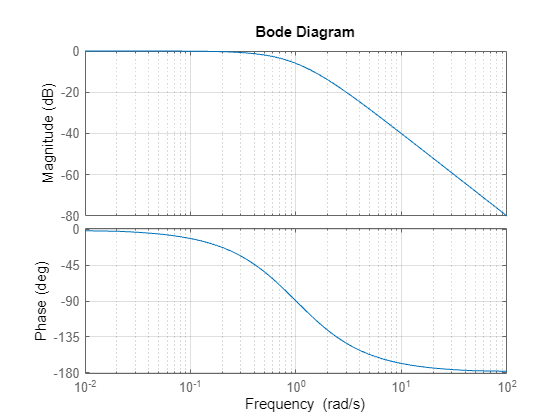

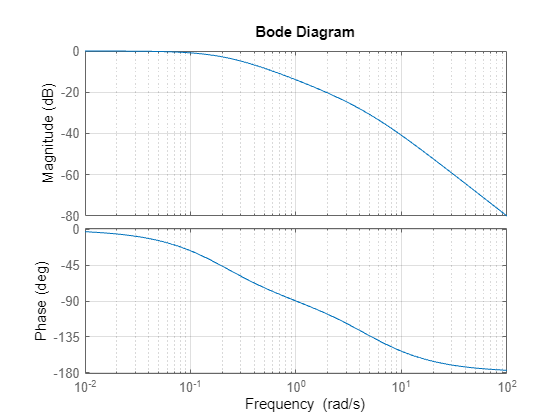

clear;
%Constants:
C = 1;
L = 1;
R = [0.5, 2, 5];
%Define Transfer Function
for i=1:length(R)
    sys(i) = tf(1, [1 , R(i),1]);
end
%Plot Bode Diagram
for i=1:length(R)
    figure;
    bode(sys(i));
    grid("on");
end


Q = 1./R

Q =     2.0000    0.5000    0.2000


#### b)

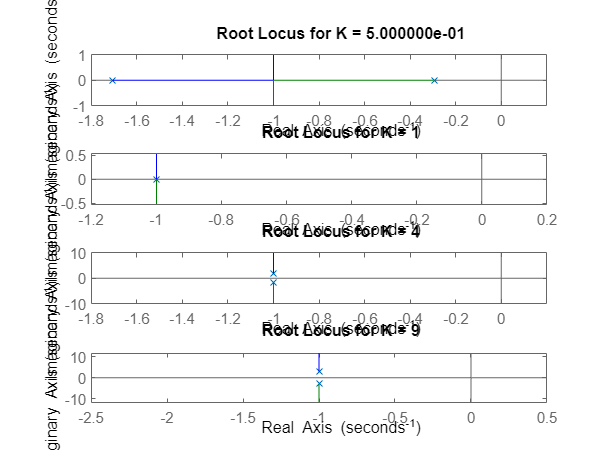

K = [0.5, 1, 4, 9];
%Feedback and rlocus plot
figure;
for i=1:length(K)
    G(i) = tf(K(i), [1, 2, 0]);
    unity = tf(1,1);  %Unity filter
    sys(i) = feedback(G(i), unity);  %feedback
    subplot(length(K) , 1 , i);
    rlocus(sys(i));title("Root Locus for K = "+sprintf("%d",K(i)));
end

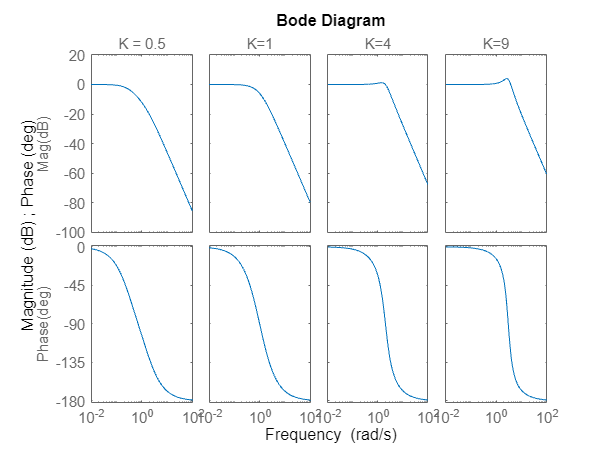

%Bode plot
figure;

bode(sys);

# Z-Transform 

## Moving Average:

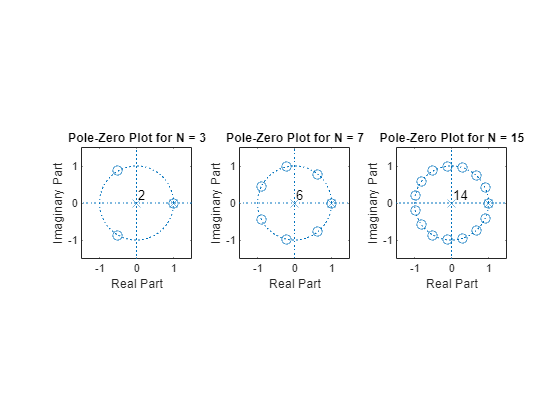

N = [3,7,15];
figure;
%Zero-Pole Plot
for i=1:length(N)
    n = N(i);
    numerator = zeros(1 , n+1);
    denominator = zeros(1,n+1);
    numerator(1) =  1./n;numerator(n+1) = -1./n;
    denominator(1) = 1; denominator(2) = -1;
   
    subplot(1,length(N),i);
    zplane(numerator,denominator); title("Pole-Zero Plot for N = " + sprintf("%d" , n));axis([-1.5 1.5 -1.5 1.5])
end

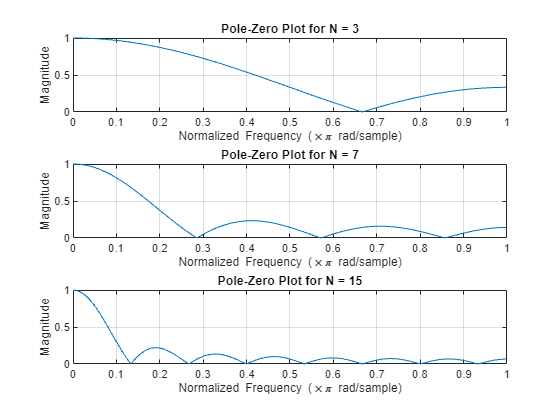

%Frequency Reponse
N = [3,7,15];
figure;
for i=1:length(N)
    n = N(i);
    numerator = zeros(1 , n+1);
    denominator = zeros(1,n+1);
    numerator(1) =  1./n;numerator(n+1) = -1./n;
    denominator(1) = 1; denominator(2) = -1;
    
    [h, w]=freqz(numerator,denominator , 512);
    subplot(length(N),1,i);
    plot(w./pi , abs(h));
    title("Pole-Zero Plot for N = " + sprintf("%d" , n));
    xlabel('Normalized Frequency (\times\pi rad/sample)');
    ylabel('Magnitude'); grid on;
end

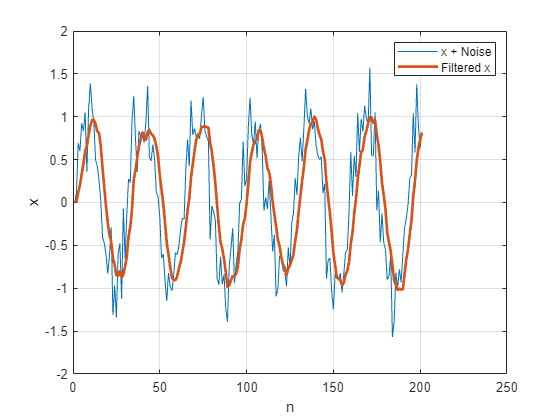

N = 7;
n = 1:201;
w = normrnd(0,0.5,[1,201]);
x = sin(pi.*n./16)+0.5.*w;
%Filter:
numerator = zeros(1 , N+1);
denominator = zeros(1,N+1);
numerator(1) =  1./N;numerator(N+1) = -1./N;
denominator(1) = 1; denominator(2) = -1;
x_filterd = filter(numerator,denominator,x);
figure;
plot(x);hold on;
plot(x_filterd, "LineWidth",2);
xlabel("n");ylabel("x"); legend("x + Noise","Filtered x");grid on;

## Inverse Via Partial Fractions

Find zeos and poles of $H(z) = \frac{z^2-0.5 z}{z^2 -z +0.5 }$

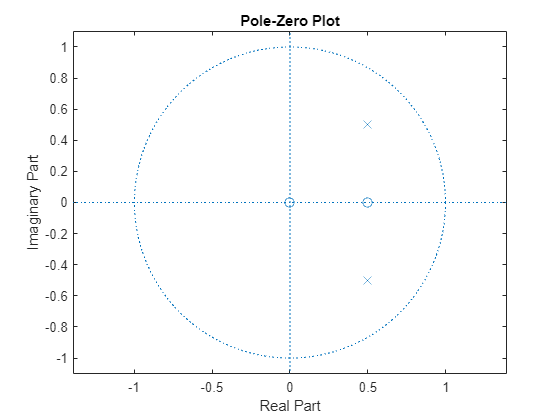

b = [1 -0.5 0];     %Numerator
a = [1 -1 +0.5];    %Denominator
H = tf(b,a);
figure;
zplane(b ,a);


%residuez
[r,p,k] = residuez(b,a);
r

r =    0.5000 + 0.0000i
   0.5000 - 0.0000i


p

p =    0.5000 + 0.5000i
   0.5000 - 0.5000i


k

k = 0


%iztrans
z = sym('z'); n = sym('n');
H = (z.^2 - 0.5 .*z)./(z.^2 - z +0.5);
h = iztrans(H)

$$h = \frac{{\left(-1\right)}^{n}\,\cos\left(\frac{3\,\pi \,n}{4}\right)}{2^{n/2}}$$

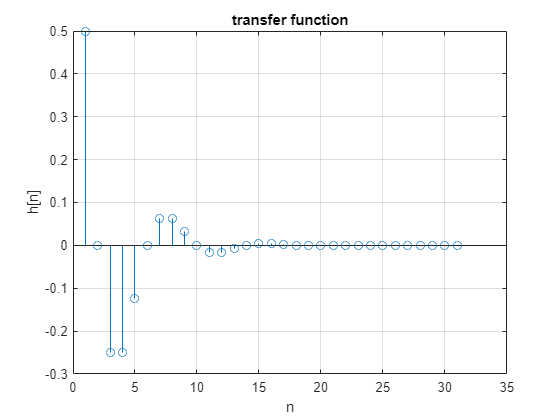

n_array = 1:31;
var = subs(h,[n],[n_array]);

figure;
stem(n_array, var);
xlabel("n");ylabel("h[n]");title("transfer function");grid on;